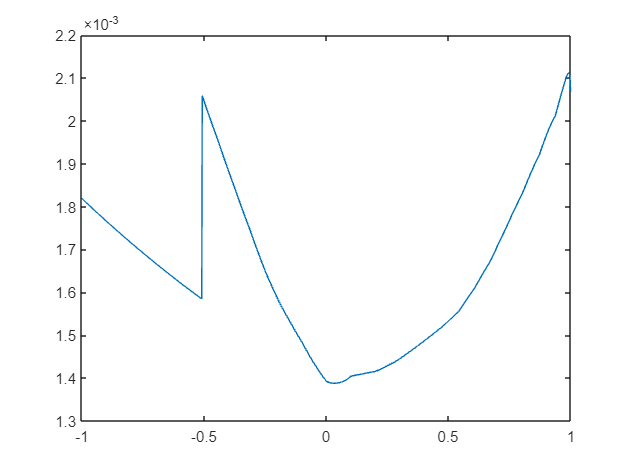

eff_int();
StateUpdate=@(input,cur_SOC,i)my_hev(9.3889,1.6667,2,0.4346,input,F1,F2);
myFullStateUpdate=@(u)my_full_horizon(u,0.4346,StateUpdate);
FullStateUpdate=@(u)my_full_horizon(u,0.4346,StateUpdate);
u=-1;
gradient=zeros(9,100);
fk=zeros(9,100);
for i=1:1000
    [fk(:,i),gradient(:,i)]=mygradient(FullStateUpdate,u,'FD',1e-2);
    u=u+2/1000;
end
plot(linspace(-1,1,1000),fk(1,:))

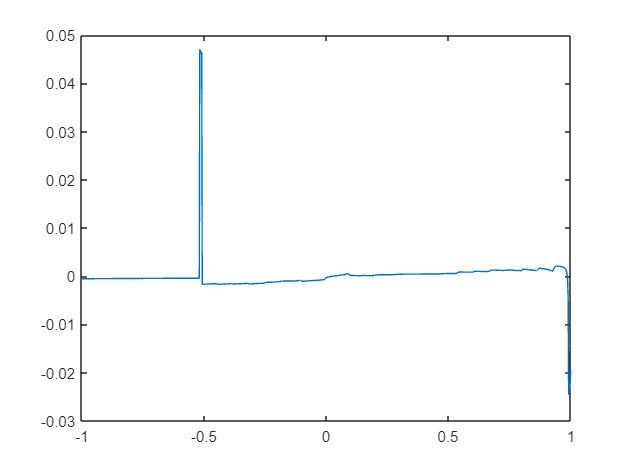

plot(linspace(-1,1,1000),gradient(1,:))

FullStateUpdate(-0.5)